# Generate Chirp 

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code imports the audio file and generates the time vector.

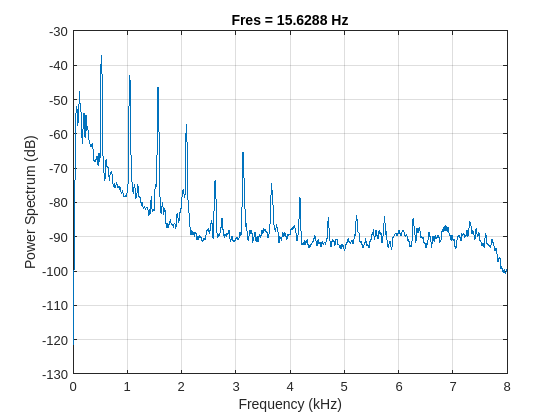

[flute, fs] = audioread("./data/NoisyFlute.wav");
flute = flute(1:7*fs);
n = numel(flute);
t = (0:n-1)'/fs;
pspectrum(flute, fs)

## Task 1

The audio spectrum has a lot of frequency spikes. You want the watermark to be easily recognizable in the spectrum, but a single tone can be difficult to differentiate from the harmonics. Instead, you can try another common signal, such as a chirp signal.

`y` `=` `chirp``(``t``,``f0``,``t1``,``f1``)`

The frequency at time `0` is `f0` and the frequency at time `t1` is `f1`.

wm = chirp(t, 6000, t(end), 7000)

wm =     1.0000
   -0.7071
    0.0000
    0.7071
   -1.0000
    0.7071
   -0.0001
   -0.7070
    1.0000
   -0.7072


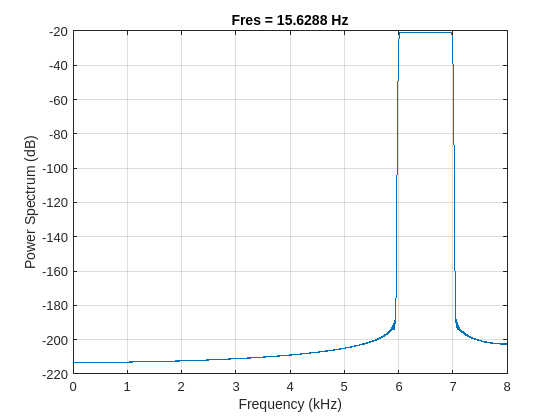

pspectrum(wm, fs)

## Task 2

Instead of a spike, the chirp creates a block of power in the spectrum. This is because chirp sweeps across the frequencies from `f0` to `f1`. Try listening to `wm` with the `soundsc` function.

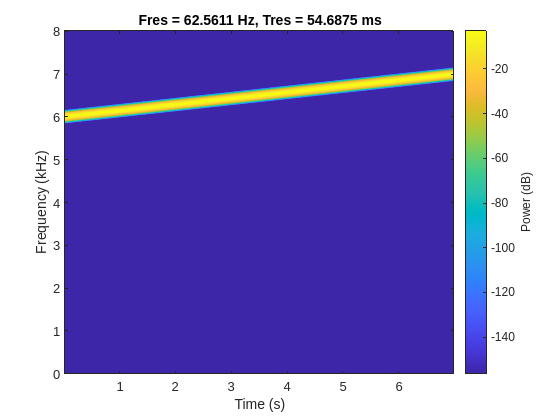

pspectrum(wm, fs, "spectrogram")

## Task 3

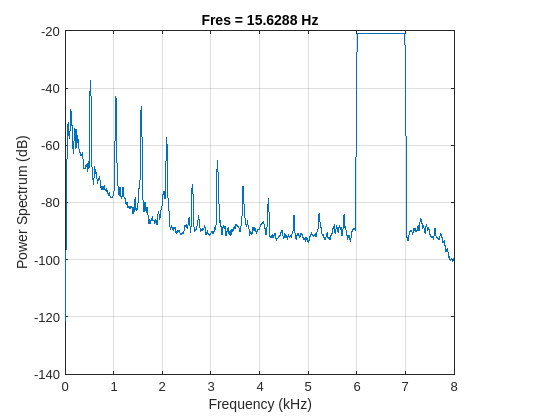

marked = wm + flute;
pspectrum(marked, fs)